## Setup kuka matricies

load('kuka_29_point_run.mat','kukapoints')
kukamats=repmat(eye(4,4),1,1,size(kukapoints,1));
RotM = eul2rotm(degtorad(kukapoints(:,4:6)));
kukamats(1:3,1:3,:)=RotM;
kukamats(1:3,4,:) = kukapoints(:,1:3)'./1000;

## Calibration

Add routine to path:

addpath('~/Documents/GIT/Camera-to-Arm-Calibration')

Can now run code to find results

Starting Arm Calibration
Extracting Chessboards


Finding Camera Parameters
Running Optimization


Saving images with initial guess and result


Done saving images
Running Bootstrap Optimization       �������   1.0%�������   2.0%�������   3.0%�������   4.0%�������   5.0%�������   6.0%�������   7.0%�������   8.0%�������   9.0%�������  10.0%�������  11.0%�������  12.0%�������  13.0%�������  14.0%�������  15.0%�������  16.0%�������  17.0%�������  18.0%�������  19.0%�������  20.0%�������  21.0%�������  22.0%�������  23.0%�������  24.0%�������  25.0%�������  26.0%�������  27.0%�������  28.0%�������  29.0%�������  30.0%�������  31.0%�������  32.0%�������  33.0%�������  34.0%�������  35.0%�������  36.0%�������  37.0%�������  38.0%�������  39.0%�������  40.0%�������  41.0%�������  42.0%�������  43.0%�������  44.0%�������  45.0%�������  46.0%�������  47.0%�������  48.0%�������  49.0%�������  50.0%�������  51.0%�������  52.0%�������  53.0%�������  54.0%�������  55.0%�������  56.0%�������  57.0%�������  58.0%�������  59.0%�������  60.0%�������  61.0%�������  62.0%�������  63.0%�������  64.0%�������  65.0%�������  66.0%�������  67.0%������

TBase =     0.9997   -0.0185    0.0141    0.2199
   -0.0176   -0.9982   -0.0565    0.1720
    0.0151    0.0563   -0.9983    2.1612
         0         0         0    1.0000


TEnd =     0.3853    0.9228    0.0019   -0.0176
    0.9224   -0.3851   -0.0283   -0.2248
   -0.0254    0.0127   -0.9996    0.1670
         0         0         0    1.0000


cameraParams =   cameraParameters with properties:

   Camera Intrinsics
                    IntrinsicMatrix: [3x3 double]
                        FocalLength: [2.4686e+03 2.4674e+03]
                     PrincipalPoint: [1.2585e+03 1.0201e+03]
                               Skew: 0

   Lens Distortion
                   RadialDistortion: [-0.3922 0.2104 -0.2271]
               TangentialDistortion: [8.4741e-04 -0.0017]

   Camera Extrinsics
                   RotationMatrices: [3x3x29 double]
                 TranslationVectors: [29x3 double]

   Accuracy of Estimation
              MeanReprojectionError: 0.1553
                 ReprojectionErrors: [100x2x29 double]
                  ReprojectedPoints: [100x2x29 double]

   Calibration Settings
                        NumPatterns: 29
                        WorldPoints: [100x2 double]
                         WorldUnits: 'm'
                       EstimateSkew: 0

TBaseStd =     0.0001    0.0045    0.0020    0.0225
    0.0023    0.0657    0.2959    0.0182
    0.0042    0.2959    0.0657    0.2209
         0         0         0         0


TEndStd =     0.1189    0.0528    0.1337    0.0018
    0.0544    0.1188    0.1965    0.0215
    0.1343    0.1970    0.0422    0.0123
         0         0         0         0


pixelErr = 13.5004

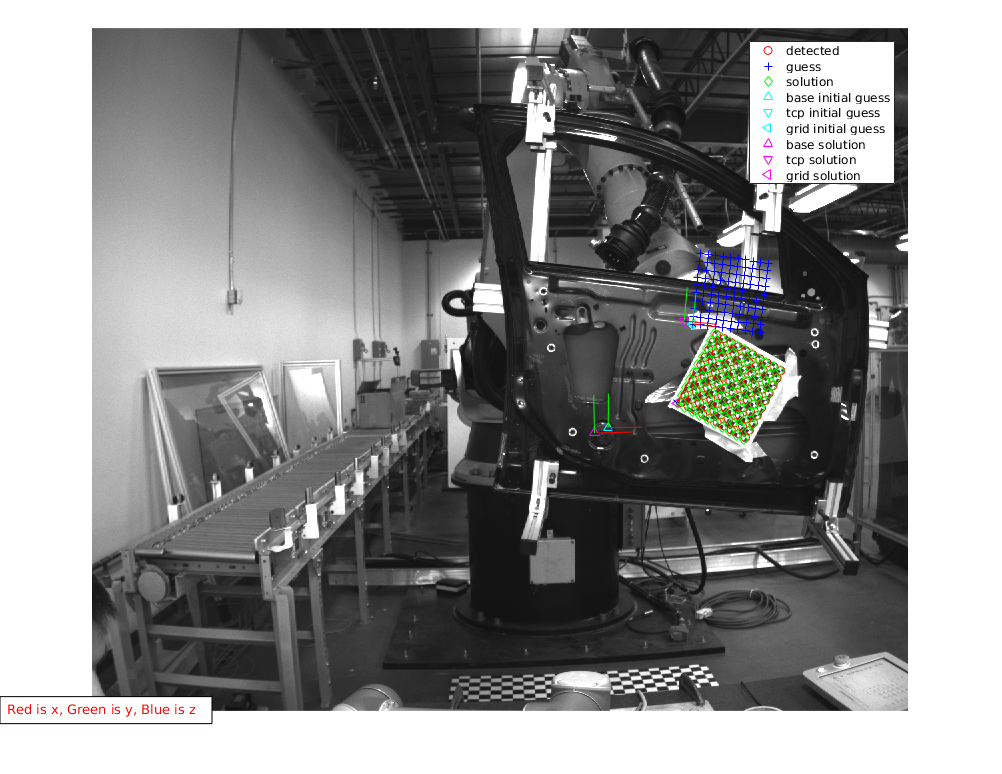

cam2base_meters = [1.0,0.0,0.0,.2850;0.0,-1.0,0.0,.1750;0.0,0.0,-1.0,2.4000;0.0,0.0,0.0,1.0];
[TBase, TEnd, cameraParams, TBaseStd, TEndStd, pixelErr] = ...
    CalCamArm('kukapics',kukamats,25.4,'errest',true,'maxBaseOffset', 2,...
    'baseEst', cam2base_meters)